clear all 
close all
clc

tuid = [9,1,6,0,2,7,2,0,7];
A = tuid(9) + 2; % amplitude [Volts]

rb = 500;      % Bit rate
fs = 32*1000;   % Sampling frequency

Tb = 1/rb;      % Bit interval
Ts = 1/fs;      % Sampling interval


N  = 30;         % Number of bits to be transmitted

## A distorted ( frequency selective) channel

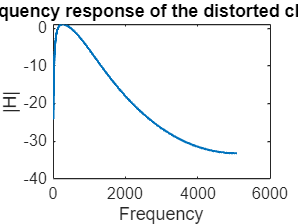

den = [1.00,-2.838,3.143,-1.709,0.458,-0.049];
num=0.1*[1,-1];
Ns = floor(Tb/Ts);

[H,w] = freqz(num,den,1024,fs); % Frequency response of the channel
figure(1)
plot(w/pi,20*log10(abs(H)),'LineWidth',2)
xlabel("Frequency")
ylabel("|H|")
title("Frequency response of the distorted channel")
set(gca,'fontsize',14)

## Transmitted and Received signal

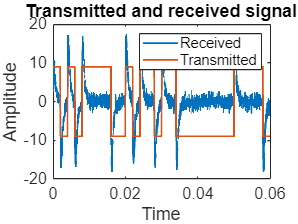

msg = randi([0,1],1,N);            % Binary data
[t,sig] = polar_nrz_lab5(msg,A,rb,fs);   % Polar Non return to zero scheme
distorted= filter(num,den,sig);     % Distorted signal
snr = 0;                            % Setting the SNR
received= awgn(distorted,snr);      % Received signal

figure(2)
plot(t,received,'LineWidth',1.5)
hold on;
plot(t,sig,'LineWidth',1.5)
hold on
xlabel("Time"), 
ylabel("Amplitude")
legend("Received","Transmitted")
title("Transmitted and received signal")
set(gca,'fontsize',14)

## Matched filtering

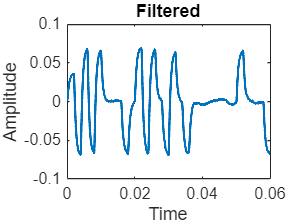

pulse = ones(1,Ns);                                     % Reference pulse
sig_filtered = filter(flip(pulse),1,received);          % Filtered signal
sig_filtered = sig_filtered/(A^2*Ns);                   % Normalizing

figure(3)
plot(t,sig_filtered,"LineWidth",2)
xlabel("Time"), 
ylabel("Amplitude")
title("Filtered")
set(gca,'fontsize',14)

## Detection

filtered = sig_filtered(Ns:Ns:end); % Sample at Tb
detected = filtered;
detected(filtered>=0)=1;            % Thresholding
detected(filtered<0)=0;
error = sum(msg~=detected)*(100/N);
disp(strcat("Error = ",num2str(error)," %"))

Error = 20 %


## Eye diagram

%eyediagram(sig_filtered,Ns);


## Task 1

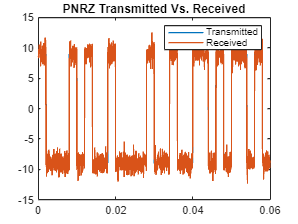

tuid = [9,1,6,0,2,7,2,0,7];
A = tuid(9) + 2; % amplitude [Volts]
rb = 500;      % Bit rate
fs = 32*1000;   % Sampling frequency
Tb = 1/rb;      % Bit interval
Ts = 1/fs;      % Sampling interval
N  = 30;         % Number of bits to be transmitted
den = [1.00,-2.838,3.143,-1.709,0.458,-0.049];
num=0.1*[1,-1];
Ns = floor(Tb/Ts);
[H,w] = freqz(num,den,1024,fs); % Frequency response of the channel
msg = randi([0,1],1,N);            % Binary data
[t,sig] = polar_nrz_lab5(msg,A,rb,fs);   % Polar Non return to zero scheme
distorted= filter(num,den,sig);     % Distorted signal

figure(4)
plot(t,sig)
hold on
plot(t,awgn(sig,0))
title('PNRZ Transmitted Vs. Received')
legend('Transmitted','Received')
hold off

%saveas(4,'Task1.png','png')

snrs = -20:2:20

snrs =    -20   -18   -16   -14   -12   -10    -8    -6    -4    -2     0     2     4     6     8    10    12    14    16    18    20


error_array = zeros([0,length(snrs)])


error_array =

  0×21 empty double matrix



for i=1:length(snrs)
    error_array(i)= CalculateErrorRate(A, N, snrs(i),Ns,distorted,msg);
end

## Task 2

error_array_distortionless = zeros([0,length(snrs)])


error_array_distortionless =

  0×21 empty double matrix



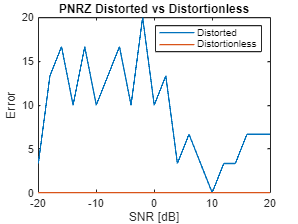

for i=1:length(snrs)
    error_array_distortionless(i) = CalculateErrorRate(A, N, snrs(i),Ns,sig,msg);
end

figure(4)
plot(snrs,error_array)
hold on
plot(snrs,error_array_distortionless)
ylabel("Error")
xlabel("SNR [dB]")
legend('Distorted','Distortionless')
title('PNRZ Distorted vs Distortionless')
saveas(4,'Task2.png','png')
hold off


[error_distorted_0db, filtered_distorted_0db] = CalculateErrorRate(A,N,0, Ns, distorted, msg);
[error_distortionless_0db, filtered_distortionless_0db] = CalculateErrorRate(A,N,0, Ns, sig, msg);


%eyediagram(filtered_distorted_0db,Ns)
%eyediagram(filtered_distortionless_0db,Ns)


## Task 3

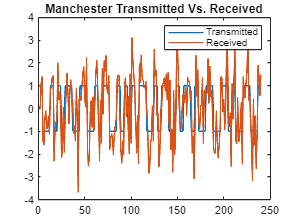

rb = 4000;      % Bit rate
fs = 32*1000;   % Sampling frequency
Tb = 1/rb;      % Bit interval
Ts = 1/fs;      % Sampling interval
N  = 30;         % Number of bits to be transmitted
den = [1.00,-2.838,3.143,-1.709,0.458,-0.049];
num=0.1*[1,-1];
Ns = floor(Tb/Ts);

[t,sig] = manchester_sig(msg,A,rb,fs);   % Polar Non return to zero scheme
distorted= filter(num,den,sig);     % Distorted signal

[error_distorted_0db, signal_distorted_0db] = CalculateErrorRate(A,N,0, Ns, distorted, msg);
[error_distortionless_0db, signal_distortionless_0db] = CalculateErrorRate(A,N,0, Ns, sig, msg);

figure(5)
plot(sig)
hold on
plot(awgn(sig,0))
title('Manchester Transmitted Vs. Received')
legend('Transmitted','Received')
hold off
saveas(5,'Task3.png','png')

%eyediagram(signal_distorted_0db,Ns)
%eyediagram(signal_distortionless_0db,Ns)

## Task 4

error_array_distorted_manchester = zeros([0,length(snrs)])


error_array_distorted_manchester =

  0×21 empty double matrix



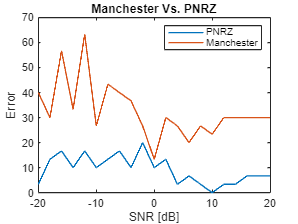

for i=1:length(snrs)
    error_array_distorted_manchester(i) = CalculateErrorRate(A, N, snrs(i),Ns,distorted,msg);
end

figure(6)
plot(snrs,error_array)
hold on
plot(snrs,error_array_distorted_manchester)
title('Manchester Vs. PNRZ')
ylabel("Error")
xlabel("SNR [dB]")
legend('PNRZ','Manchester')
saveas(6,'Task4.png','png')

## Error Rate/SNR Function

function [error, sig_filtered] = CalculateErrorRate(A, N, snr, Ns, distorted, msg)
    received= awgn(distorted,snr);      % Received signal
    pulse = ones(1,Ns);                                     % Reference pulse
    sig_filtered = filter(flip(pulse),1,received);          % Filtered signal
    sig_filtered = sig_filtered/(A^2*Ns);                   % Normalizing
    filtered = sig_filtered(Ns:Ns:end); % Sample at Tb
    detected = filtered;
    detected(filtered>=0)=1;            % Thresholding
    detected(filtered<0)=0;
    error = sum(msg~=detected)*(100/N);
end